linethickness = 2; % Line thickness option
textscale = 1.5; % Text and legend scale option
Io = Vin ./ Rl;
Iripple = 1000E-3;
fsw = 50e6;
tr = 1E-9;
tf = 1E-9;
tcross = tr + tf;
RDS = 450E-3;
Qg = 5*149e-12;
duty = 0.5;
ntransistors=2

ntransistors = 2

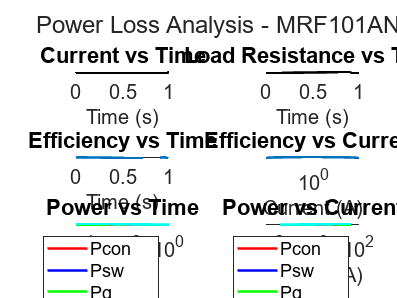


% Call the function with the given values
[Pcon, Pg, Psw, Pwaste, Pdeliver, efficiency] = power_loss_analysis(RDS, Io, Iripple, duty, nsamples, Qg, Vg, fsw, Vin, Rl, tcross, t, linethickness, textscale, 'MRF101AN', ntransistors);

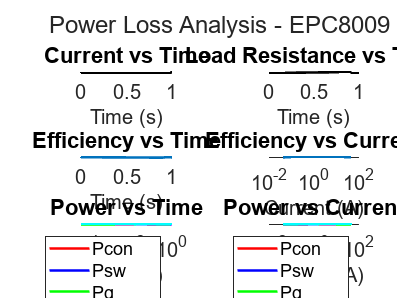


linethickness = 2; % Line thickness option
textscale = 1.5; % Text and legend scale option
tr = 0.5E-9;
tf = 0.5E-9;
tcross = tr + tf;
RDS = 90E-3;
Qg = 370e-12;
duty = 0.5;

[Pcon, Pg, Psw, Pwaste, Pdeliver, efficiency] = power_loss_analysis(RDS, Io, Iripple, duty, nsamples, Qg, Vg, fsw, Vin, Rl, tcross, t, linethickness, textscale, 'EPC8009', ntransistors);

function [Pcon, Pg, Psw, Pwaste, Pdeliver, efficiency] = power_loss_analysis(RDS, Io, Iripple, duty, nsamples, Qg, Vg, fsw, Vin, Rl, tcross, t, linethickness, textscale, titleStr, ntransistors)
    % Define the number of samples
    
    % Calculate Conduction Losses
    Pcon = (RDS.*((2*Io/ntransistors).^2))/1;
    
    % Gate Charge Losses
    Pg = ntransistors * Qg * Vg * fsw;
    
    % Switching Losses
    Psw = ntransistors * Vin * Io * tcross / 2 * fsw / 1;
    
    % Total Power Wasted
    Pwaste = (Pcon + Psw + Pg);
    
    % Power Delivered
    Pdeliver = (Vin .* Io .* duty) ./ 1;
    
    % Efficiency
    efficiency = 1 - 1 * (1 * Pwaste ./ Pdeliver) / 1;

    % Plot the calculated values for easy visualization
    figure('Name', ['Power Loss Analysis - ' titleStr], 'NumberTitle', 'off');
    tiledlayout(3, 2);
    
    % Add a title above all plots
    sgtitle(['Power Loss Analysis - ' titleStr], 'FontSize', 12 * textscale);

    % Plot Current vs Time
    nexttile;
    plot(t, Io, 'k', 'LineWidth', linethickness);
    title('Current vs Time');
    xlabel('Time (s)');
    ylabel('Current (A)');
    set(gca, 'FontSize', 10 * textscale);
    set(get(gca, 'XLabel'), 'FontSize', 10 * textscale);
    set(get(gca, 'YLabel'), 'FontSize', 10 * textscale);
    grid on;
    
    % Plot Load Resistance vs Time
    nexttile;
    plot(t, Rl, 'k', 'LineWidth', linethickness);
    title('Load Resistance vs Time');
    xlabel('Time (s)');
    ylabel('Load Resistance (Ohms)');
    set(gca, 'FontSize', 10 * textscale);
    set(get(gca, 'XLabel'), 'FontSize', 10 * textscale);
    set(get(gca, 'YLabel'), 'FontSize', 10 * textscale);
    grid on;

    % Plot Efficiency vs Time
    nexttile;
    plot(t, efficiency, 'LineWidth', linethickness);
    title('Efficiency vs Time');
    xlabel('Time (s)');
    ylabel('Efficiency');
    ylim([0.1, 1.1]);
    set(gca, 'FontSize', 10 * textscale);
    set(get(gca, 'XLabel'), 'FontSize', 10 * textscale);
    set(get(gca, 'YLabel'), 'FontSize', 10 * textscale);
    grid on;

    % Plot Efficiency vs Current 
    nexttile;
    loglog(Io, efficiency, 'LineWidth', linethickness);
    title('Efficiency vs Current');
    xlabel('Current (A)');
    ylabel('Efficiency');
    ylim([0.1, 1.1]);
    set(gca, 'FontSize', 10 * textscale);
    set(get(gca, 'XLabel'), 'FontSize', 10 * textscale);
    set(get(gca, 'YLabel'), 'FontSize', 10 * textscale);
    grid on;

    % Plot Power Losses vs Time 
    nexttile;
    loglog(t, Pcon, 'r', 'LineWidth', linethickness);
    hold on;
    loglog(t, Psw, 'b', 'LineWidth', linethickness);
    loglog(t, Pg * ones(size(t)), 'g', 'LineWidth', linethickness); % Pg is constant, replicate for all time steps
    loglog(t, Pwaste, 'm', 'LineWidth', linethickness);
    loglog(t, Pdeliver, 'c', 'LineWidth', linethickness);
    title('Power vs Time');
    xlabel('Time (s)');
    ylabel('Power (W)');
    legend('Pcon', 'Psw', 'Pg', 'Pwaste', 'Pdeliver');
    set(gca, 'FontSize', 10 * textscale);
    set(get(gca, 'XLabel'), 'FontSize', 10 * textscale);
    set(get(gca, 'YLabel'), 'FontSize', 10 * textscale);
    set(findobj(gca, 'Type', 'Legend'), 'FontSize', 10 * textscale);
    grid on;
    hold off;

    % Plot Power Losses vs Current 
    nexttile;
    loglog(Io, Pcon, 'r', 'LineWidth', linethickness);
    hold on;
    loglog(Io, Psw, 'b', 'LineWidth', linethickness);
    loglog(Io, Pg * ones(size(Io)), 'g', 'LineWidth', linethickness); % Pg is constant, replicate for all current steps
    loglog(Io, Pwaste, 'm', 'LineWidth', linethickness);
    loglog(Io, Pdeliver, 'c', 'LineWidth', linethickness);
    title('Power vs Current');
    xlabel('Current (A)');
    ylabel('Power (W)');
    legend('Pcon', 'Psw', 'Pg', 'Pwaste', 'Pdeliver');
    set(gca, 'FontSize', 10 * textscale);
    set(get(gca, 'XLabel'), 'FontSize', 10 * textscale);
    set(get(gca, 'YLabel'), 'FontSize', 10 * textscale);
    set(findobj(gca, 'Type', 'Legend'), 'FontSize', 10 * textscale);
    grid on;
    hold off;
end